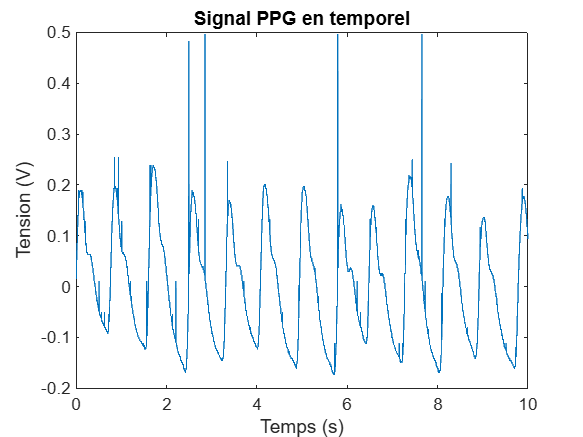

%%% PARTIE 1) VISUALISATION DES DONNEES
clear all
close all
load PPG.mat
load PPG_2.mat

%-------------------------------------------------------------------------------------------------------
%Signal PPG réel acquis par le capteur et numérisé par le CAN
loadedData = load('S_PPG_reel.mat');
S_PPG_reel = loadedData.S;

%Pré-traitement des données
s_PPG_r = S_PPG_reel(:,2)';
nech_PPG_r = length(s_PPG_r);
T_r = (S_PPG_reel(:,1) - S_PPG_reel(1,1))';
Te_r = mean(diff(T_r));
Fe_r = 1/Te_r;

%-------------------------------------------------------------------------------------------------------
%Signal PPG donné
s_PPG = s;
nech_PPG = length(s_PPG);
Te = 1/Fe;
T = 0:Te:(nech_PPG-1)*Te;

%------------------------------------------------------------------------------------------------------
%Signal PPG LONG donné
s_PPG_long = sortie_out(:,2)';
nech_PPG_long = length(s_PPG_long);
T_long = (sortie_out(:,1) - sortie_out(1,1))';
Te_long = nech_PPG_long/T_long(nech_PPG_long);
Fe_long = 1/Te_long;

%------------------------------------------------------------------------------------------------------
%Signal PPG 2 donné
s_PPG_2 = sortie_out(:,2)';
nech_PPG_2 = length(s_PPG_2);
T_2 = (sortie_out(:,1) - sortie_out(1,1))';
Te_2 = mean(diff(T_2));
Fe_2 = 1/Te_2;

%------------------------------------------------------------------------------------------------------
%Signal PPG créé
A1 = 0.25;
A2 = 0.125;
B1 =  0.2;
B2 = 0.15;
Vdc = 2.5;
f = 1; %Pour avoir une fréquence du signal de 1Hz et donc 60 BPM


%Artéfacts à la mesure
pas_art = 300 ;
pas_art_2 = 101 ;

artefacts = zeros(1, nech_PPG) ;

artefacts(1:pas_art:end) = 0.5 ;
artefacts(1:pas_art_2:end) = 0.1 ;

%Dérivation du signal 
f_deriv = 0.2; 
derive = 0.05*sin(2*pi*f_deriv*T) ;


bruit_blanc = 0.005*randn(1,nech_PPG) ;
bruit_alim = 0.01*sin(2*pi*50*T) ;

s_cree_typeA = A1*sin(2*pi*f*T) + A2*sin(2*pi*(2*f)*T -pi/8) + Vdc + bruit_blanc + bruit_alim + derive + artefacts ;

s_cree_typeB = B1*sin(2*pi*f*T) + B2*sin(2*pi*(2*f)*T -pi/3) + Vdc + bruit_blanc + bruit_alim + derive + artefacts;

%------------------------------------------------------------------------------------------------------
%Choix du signal étudié
s_choisi = s_PPG_2; %Signal étudié
T_choisi = T_2;     %Base de temps
Fe = Fe_2;          %Fréquence d'échantillonage 

nech = length(s_choisi); %Nombre d'échantillons 

s_centre = s_choisi - mean(s_choisi); %On centre le signal pour mieux visualiser (suppression composante continue)

plot(T_choisi, s_centre);
title('Signal PPG en temporel')
xlabel('Temps (s)');
ylabel('Tension (V)');

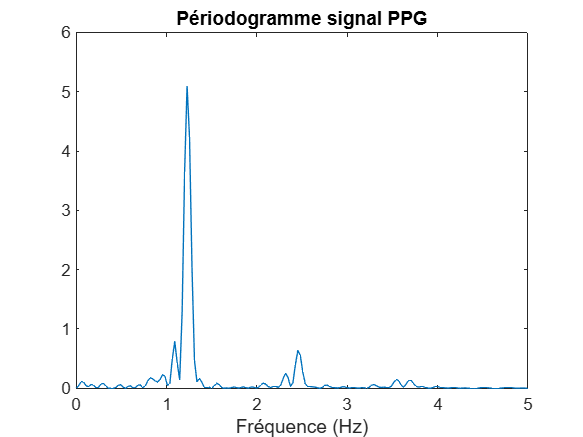

%------------------------------------------------------------------------------------------------------
%Analyse fréquentielle: Périodogramme

fact_zeropadding = round( 3 + log2(nech/(2^nextpow2(nech))) )  ; % facteur de zero-padding : 
% si =1, on fait du zero-padding jusqu'à la puissance de 2 supérieure
% si =2, jusqu'à 2 * puissance de 2 supérieure,
% si =3, jusqu'à 4 * puissance de 2 supérieure etc...

nfft = 2^( nextpow2(nech) + fact_zeropadding - 1 ) ; % taille sur laquelle est calculée la FFT
Speriodo = ( abs(fft(s_centre,nfft)).^2 )/ nfft;     % initialisation du vecteur "Périodogramme"

% Pour afficher le résultat, il faut créer un vecteur "frequences" pour l'axe des abscisses.
% On peut travailler en fréquences physiques (Herz) ou normalisées.

frequencesHerz = linspace(0, Fe, nfft); % initialisation du vecteur
frequencesNorm = linspace(0, 1, nfft); % initialisation du vecteur

%%% Affichage
plot(frequencesHerz,Speriodo); 
xlim([0,5]);
title('Périodogramme signal PPG'); xlabel('Fréquence (Hz)');

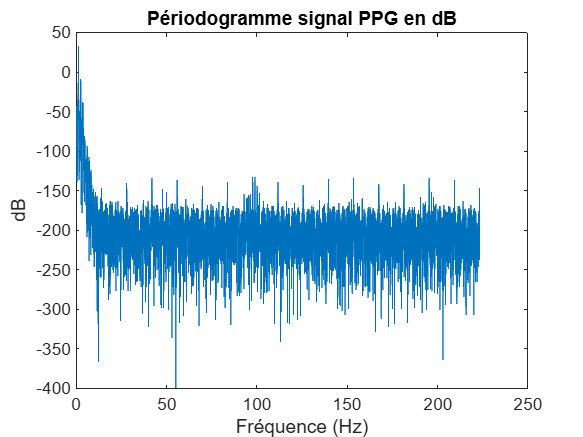



%Nous avons seulement besoin de voir le signal jusqu'a nfft/2 
%Pour plus de visibilite nous allons voir le signal en decibel

SperiodoDB = 20*log(Speriodo(2:nfft/2)); % on démarre a 2 pour enlever la premiere harmonique qui est trop grande
frequencesHerzmi = frequencesHerz(1:nfft/2);
frequencesNormmi = frequencesHerzmi/Fe;


figure('Name','Périodogramme complet en dB');
plot(frequencesHerzmi(1,2:nfft/2),SperiodoDB); 
title('Périodogramme signal PPG en dB'); xlabel('Fréquence (Hz)'); ylabel('dB');

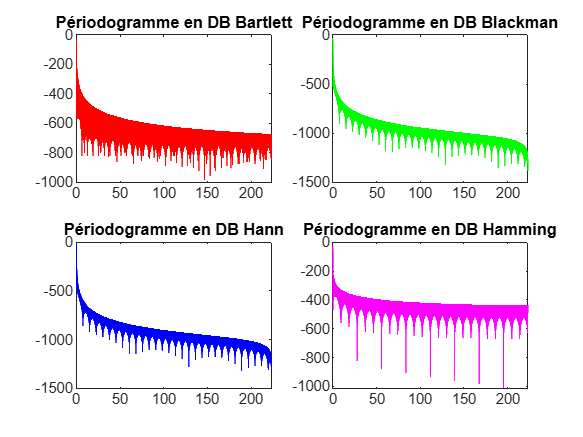

%figure('Name','Périodogramme signal synthétique normalisé en DB');
%plot(frequencesNormmi,SperiodoDB);
%title('Périodogramme normalisé en DB'); xlabel('Fréquences normalisées');


%%% PARTIE 2) PERIODOGRAMME DES DIFFERENTES FENÊTRES
%HAMMING
Sper_ham = zeros(nfft,1);
Sper_ham = (1/nech)*abs(fft(hamming(nech).*s_centre,nfft)).^2;
Sper_hamDB=20*log(Sper_ham(1:nfft/2));

%HANN
Sper_han = zeros(nfft,1);
Sper_han = (1/nech)*abs(fft(hann(nech).*s_centre,nfft)).^2;
Sper_hanDB=20*log(Sper_han(1:nfft/2));

%BLACKMAN
Sper_bla = zeros(nfft,1);
Sper_bla = (1/nech)*abs(fft(blackman(nech).*s_centre,nfft)).^2;
Sper_blaDB=20*log(Sper_bla(1:nfft/2));

%BARTLETT
Sper_bar = zeros(nfft,1);
Sper_bar = (1/nech)*abs(fft(bartlett(nech).*s_centre,nfft)).^2;
Sper_barDB=20*log(Sper_bar (1:nfft/2));

%Tracés
figure('Name','Périodogramme complet en DB');
subplot(2,2,1); plot(frequencesHerzmi,Sper_barDB','r');
title('Périodogramme en DB Bartlett')

subplot(2,2,2); plot(frequencesHerzmi,Sper_blaDB','g');
title('Périodogramme en DB Blackman')

subplot(2,2,3); plot(frequencesHerzmi,Sper_hanDB','b');
title('Périodogramme en DB Hann')

subplot(2,2,4); plot(frequencesHerzmi,Sper_hamDB','m');
title('Périodogramme en DB Hamming')

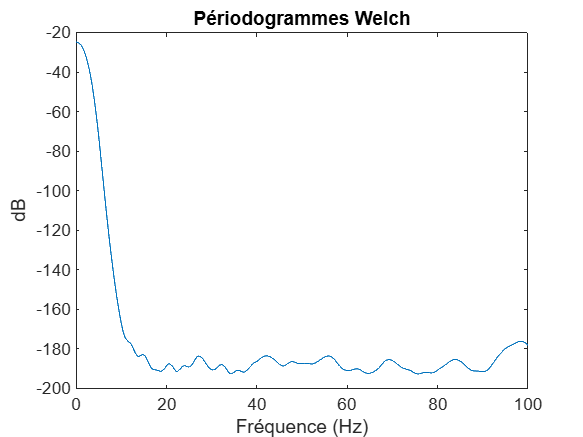

%WELCH
fenetre = 150; %valeur fixé 
chevauchement = 75; %valeur fixé

Sper_welch = pwelch(s_centre,fenetre,chevauchement,nfft);
Sper_welchDB = 20*log(Sper_welch(2:nfft/2));
figure();
plot(frequencesHerzmi(1,2:nfft/2),Sper_welchDB);
xlim([0,100]);
%Si on veut comparer les fenêtres plus en détail on peut les afficher ensembles
%hold on
%plot(frequencesHerzmi,Sper_barDB','r');
%plot(frequencesHerzmi,Sper_blaDB','g');
%plot(frequencesHerzmi,Sper_hanDB','b');
%plot(frequencesHerzmi,Sper_hamDB','m');
%hold off

title('Périodogrammes Welch'); xlabel('Fréquence (Hz)'); ylabel('dB');

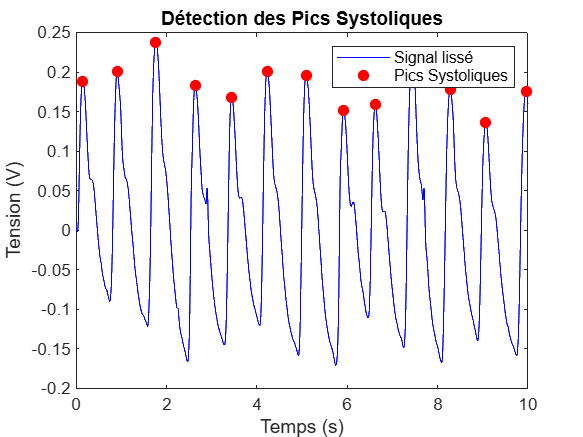


%%% PARTIE 3) Pré-processing = FILTRAGE DU BRUIT_______________________________

%Filtre de Savitzky-Golay

order = 2;
framelen = 21;
s_centre_lisse_sgolay = sgolayfilt(s_centre,order,framelen);

%Filtre RIF
 
coef_passebas = load('Coeff_hamming_5_30_47.mat');
A = coef_passebas.a;
B = coef_passebas.b;
s_centre_lisse_RIF = filter(B,A,s_centre);

%Combinaison filtres RIF et Savitzky-Golay
s_centre_lisse_sgo_rif = sgolayfilt(s_centre_lisse_RIF,order,framelen);


%Choix du filtre utilisé
s_centre_lisse = s_centre_lisse_sgo_rif; 


%%% PARTIE 4) DETECTION DES PICS SYSTOLIQUE

ECART_MIN = Fe/(2*f);                %distance minimale entre 2 pics
AMP_MIN = 0.5*max(s_centre_lisse);   %seuil detection de pics

[pics, locs] = findpeaks(s_centre_lisse, 'MinPeakHeight', AMP_MIN,'MinPeakDistance', ECART_MIN);

% Les indices des pics trouvés par findpeaks
Indices_systoliques = locs;

%Affichage des résultats

figure();
plot(T_choisi, s_centre_lisse, '-b'); % Tracer le signal original
hold on;
plot(T_choisi(Indices_systoliques), s_centre_lisse(Indices_systoliques), 'ro', 'MarkerFaceColor', 'r'); % Marqueurs rouges pour les pics systoliques
xlabel('Temps (s)');
ylabel('Tension (V)');
title('Signal PPG filtré');
title('Détection des Pics Systoliques');
legend('Signal lissé', 'Pics Systoliques');
hold off;

drawnow;

%Calcul du BPM 
DELTA = diff(T_choisi(Indices_systoliques));
Rythme_cardiaque = mean(DELTA); 
Frequence_cardiaque = 1/Rythme_cardiaque;  
BPM = Frequence_cardiaque*60;

%Calcul de l'écart type
BPM_liste = 60*(1./DELTA);
variance_BPM = var(BPM_liste);
ecart_type_BPM = sqrt(variance_BPM);

%%% PARTIE 5) TEST D'ARYTHMIE, DE TACHYCARDIE

%Test de neyman-pearson pour l'arythmie
alpha = 0.5;
sigma0 = 15;
X = DELTA./Fe;
test = test_neyman_pearson(X,sigma0,alpha);
if test == 1
    display('Le patient souffre d''arythmie cardiaque');
else
    display('Le patient ne fait pas d''arythmie cardiaque');
end

Le patient souffre d'arythmie cardiaque


%Test de tachycardie
if BPM < 50
    display('Le patient souffre de tachycardie');
elseif BPM > 100
    display('Le patient souffre de bradycardie');
else 
    display('Aucune anomalie détectée');
end

Aucune anomalie détectée


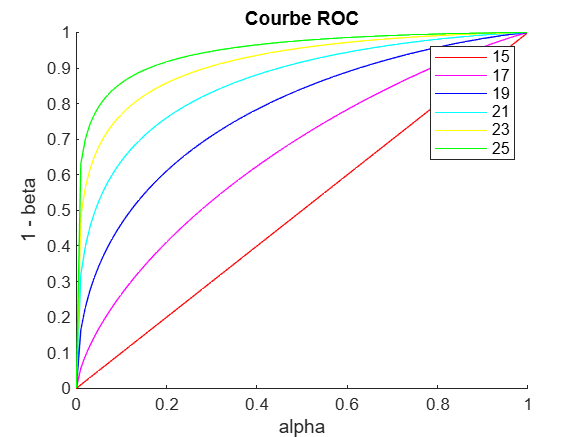

%Puissance du test: Courbe ROC

alpha_x = 0:0.01:1;                 % Valeurs de alpha (risque de faux positif)

ordre_roc = length(BPM_liste) - 1;  % Nombre de points pour la courbe ROC

sigma1 = [15; 17; 19; 21; 23; 25];  % Variances alternatives

for i = 1:length(sigma1)
    beta(i, :) = chi2cdf( (sigma0 / sigma1(i))^2 * chi2inv(1 - alpha_x, ordre_roc), ordre_roc);
end

puissance = 1 - beta;

% Tracé des courbes ROC
figure();
hold on;
plot(alpha_x, puissance(1, :), '-r');
plot(alpha_x, puissance(2, :), '-m');
plot(alpha_x, puissance(3, :), '-b');
plot(alpha_x, puissance(4, :), '-c');
plot(alpha_x, puissance(5, :), '-y');
plot(alpha_x, puissance(6, :), '-g');
xlabel('alpha');
ylabel('1 - beta');
title('Courbe ROC');
legend('15','17','19', '21 ', '23', '25');
hold off;

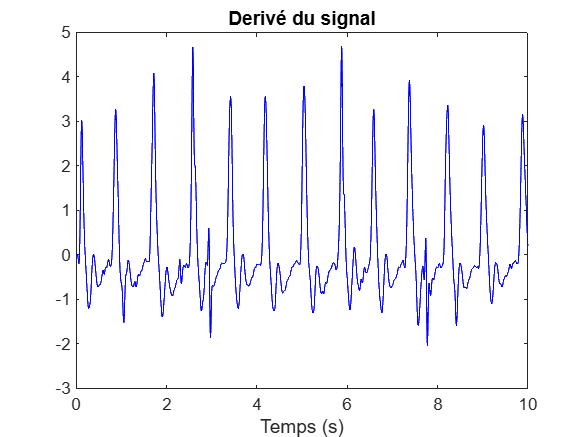

    
%%% PARTIE 6) DETECTION PICS DIASTOLIQUES

% 3 types de filtre testé sur la dérivé
deriv_s = gradient(s_centre_lisse, T_choisi);
order_d = 2;
deriv_s_lisse_sgolay = sgolayfilt(deriv_s,order_d,framelen); 
derive_s_lisse_filt = filter(B,A,deriv_s); %entre 5 et 30 Hz

deriv_s_lisse = derive_s_lisse_filt; %choix 

% Affichage de la dérivé
figure();
plot(T_choisi, deriv_s_lisse, '-b');
title('Derivé du signal'); xlabel('Temps (s)')

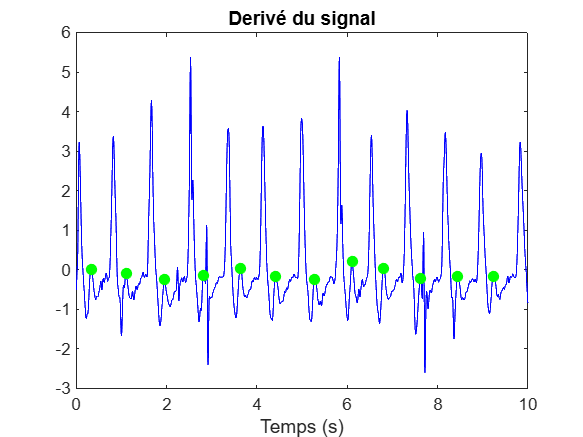


%On fera l'étud pour un signal PPG de type A
eps = sqrt(var(deriv_s_lisse));
Indices_diastoliques = [];

for i = 2:nech-1
    if (deriv_s_lisse(i)>deriv_s_lisse(i-1)) && (deriv_s_lisse(i)>deriv_s_lisse(i+1)) && (deriv_s_lisse(i)<0.4) && (deriv_s_lisse(i)> -0.4) && (s_centre_lisse(i)>0)
        Indices_diastoliques = [Indices_diastoliques, i];
    end
end

%On veut éviter les doublons
Indices_diastoliques_corrige = [];
for i = 2:length(Indices_diastoliques)
    if Indices_diastoliques(i)-Indices_diastoliques(i-1)>100
        Indices_diastoliques_corrige = [Indices_diastoliques_corrige, Indices_diastoliques(i)];
    end
end

Indices_diastoliques = Indices_diastoliques - 22 ; %décalage temporel lié au filtre choisi (0.05 * Fe)

figure();
plot(T_choisi, deriv_s, '-b');
hold on
plot(T_choisi(Indices_diastoliques), deriv_s(Indices_diastoliques), 'go', 'MarkerFaceColor', 'g');
title('Derivé du signal'); xlabel('Temps (s)')

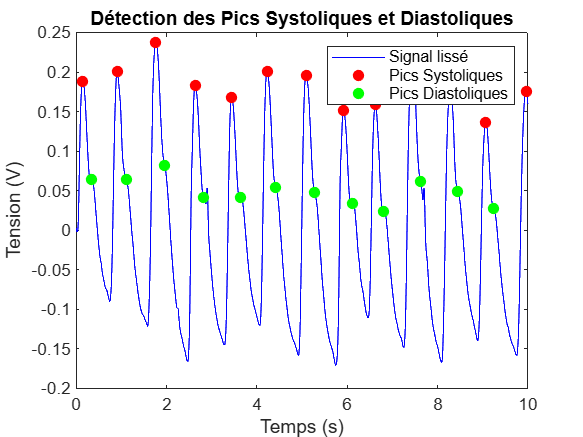


figure();
plot(T_choisi, s_centre_lisse, '-b'); % Tracer le signal original
hold on;
plot(T_choisi(Indices_systoliques), s_centre_lisse(Indices_systoliques), 'ro', 'MarkerFaceColor', 'r'); % Marqueurs rouges pour les pics systoliques
plot(T_choisi(Indices_diastoliques), s_centre_lisse(Indices_diastoliques), 'go', 'MarkerFaceColor', 'g');
xlabel('Temps (s)');
ylabel('Tension (V)');
title('Détection des Pics Systoliques et Diastoliques');
legend('Signal lissé', 'Pics Systoliques', 'Pics Diastoliques');
hold off;

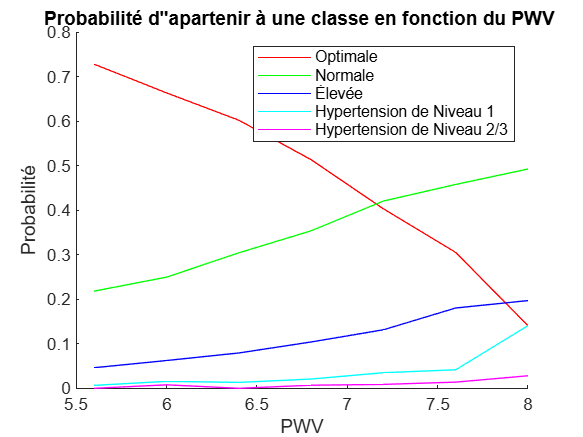


%%% PARTIE 7) PROBABILTE D'APPARTENANCE A UNE CLASSE

%Calcul de la vitesse d'onde de pouls: PWV
dist_coeur_doigt = 1 ; %donnée

DELTA_dia_sys = mean( T_choisi(Indices_diastoliques) - T_choisi(Indices_systoliques(1:end-1)) ); 

PWV = 2*dist_coeur_doigt/DELTA_dia_sys;
% On vas ensuite déterminer la probabilité de vous trouver dans chacune des classes de pression artérielle.
% classes = {'Optimale', 'Normale', 'Élevée', 'Hypertension de Niveau 1', 'Hypertension de Niveau 2/3'};

PWV_vect = [5.6; 6; 6.4; 6.8; 7.2; 7.6; 8];
PWV_mat = [110 33 7 1 0; 85 32 8 2 1; 91 46 12 2 0; 74 51 15 3 1; 46 48 15 4 1; 22 33 13 3 1; 10 35 14 10 2];
Proba_classes = PWV_mat ./sum(PWV_mat,2) ;
figure();
hold on;
plot(PWV_vect, Proba_classes(:, 1), '-r');
plot(PWV_vect, Proba_classes(:, 2), '-g');
plot(PWV_vect, Proba_classes(:, 3), '-b');
plot(PWV_vect, Proba_classes(:, 4), '-c');
plot(PWV_vect, Proba_classes(:, 5), '-m');
xlabel('PWV');
ylabel('Probabilité');
title('Probabilité d"apartenir à une classe en fonction du PWV ');
legend('Optimale', 'Normale', 'Élevée', 'Hypertension de Niveau 1', 'Hypertension de Niveau 2/3');
hold off;

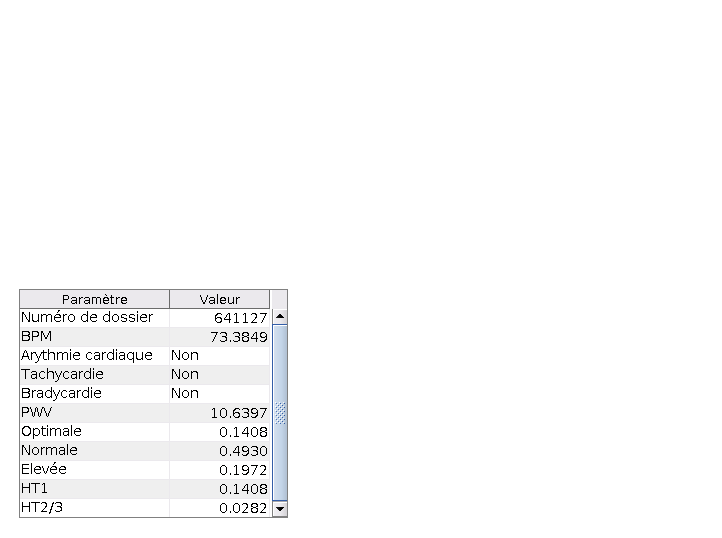

%%% PARTIE 8) R2CAPITULATIF DES DONEES DU PATIENT

if PWV <5.6
    classe_patient = Proba_classes(1, :);
elseif (PWV >= 5.6) && (PWV < 6) 
    classe_patient = Proba_classes(2, :);
elseif (PWV >= 6) && (PWV < 6.4) 
    classe_patient = Proba_classes(3, :);
elseif (PWV >= 6.4) && (PWV < 6.8) 
    classe_patient = Proba_classes(4, :);
elseif (PWV >= 6.8) && (PWV < 7.2) 
    classe_patient = Proba_classes(5, :);
elseif (PWV >= 7.2) && (PWV < 7.6) 
    classe_patient = Proba_classes(6, :);
else
    classe_patient = Proba_classes(7, :);
end

Opt = classe_patient(1);
Norm = classe_patient(2);
El = classe_patient(3);
HT1 = classe_patient(4);
HT23 = classe_patient(5);


patientData = {
    'Numéro de dossier', 641127;
    'BPM', BPM;
    'Arythmie cardiaque', 'Non';
    'Tachycardie', 'Non';
    'Bradycardie', 'Non';
    'PWV', PWV;
    'Optimale', Opt ;
    'Normale', Norm  ;
    'Elevée', El ;
    'HT1', HT1 ;
    'HT2/3', HT23 ;
};

% Création du tableau
figure();

t = uitable('Data', patientData,'ColumnName', {'Paramètre', 'Valeur'},'RowName', [], 'Position', [20, 20, 270, 230]) ;

t.ColumnWidth = {150, 100};